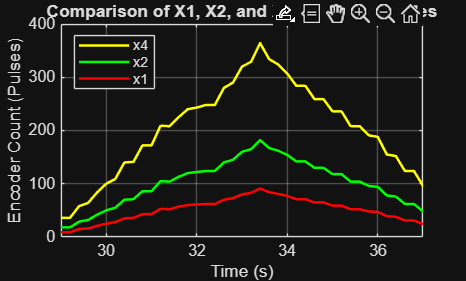

% ===== ส่วนที่ 1: เตรียมข้อมูล =====
clear; clc; close all;

% --- ตั้งค่าไฟล์และชื่อสัญญาณ (กรุณาแก้ไขให้ถูกต้อง) ---
mat_filename = '5.mat'; % <--- ใส่ชื่อไฟล์ .mat ของคุณที่นี่
x1_name = 'x1'; % <--- ใส่ชื่อสัญญาณ X1 ของคุณ
x2_name = 'x2'; % <--- ใส่ชื่อสัญญาณ X2 ของคุณ
x4_name = 'x4'; % <--- ใส่ชื่อสัญญาณ X4 ของคุณ

% ===== ส่วนที่ 2: โหลดและดึงข้อมูล =====
try
    load(mat_filename);
catch
    error('ไม่พบไฟล์ .mat ที่ชื่อ "%s".', mat_filename);
end

try
    sigX1 = data.get(x1_name);
    sigX2 = data.get(x2_name);
    sigX4 = data.get(x4_name);
catch
    error('ไม่พบชื่อสัญญาณในไฟล์ .mat. กรุณาตรวจสอบชื่อสัญญาณให้ครบถ้วน');
end

% "บีบ" มิติข้อมูล
timeX1 = squeeze(sigX1.Values.Time);
dataX1 = squeeze(sigX1.Values.Data);

timeX2 = squeeze(sigX2.Values.Time);
dataX2 = squeeze(sigX2.Values.Data);

timeX4 = squeeze(sigX4.Values.Time);
dataX4 = squeeze(sigX4.Values.Data);

% ===== ส่วนที่ 3: พล็อตกราฟ =====
h_fig = figure; % สร้างหน้าต่างกราฟใหม่

% --- พล็อตกราฟทั้ง 3 เส้น ---
plot(timeX4, dataX4, 'y', 'LineWidth', 1.5); % X4 - สีเหลือง
hold on;
plot(timeX2, dataX2, 'g', 'LineWidth', 1.5); % X2 - สีเขียว
plot(timeX1, dataX1, 'r', 'LineWidth', 1.5); % X1 - สีแดง
hold off;

% ===== ส่วนที่ 4: ปรับแต่งกราฟโดยรวม =====
title('Comparison of X1, X2, and X4 Decoding Modes');
xlabel('Time (s)');
ylabel('Encoder Count (Pulses)');
legend(x4_name, x2_name, x1_name, 'Location', 'northwest');
grid on;
box on;

% ===== ส่วนที่ 5: ปรับแต่ง UI เป็น Dark Mode (เอา % ออกเพื่อใช้งาน) =====
% set(h_fig, 'Color', [0.15 0.15 0.15]);
% ax = gca;
% ax.Color = [0.1 0.1 0.1];
% ax.GridColor = [0.4 0.4 0.4]; ax.GridAlpha = 0.5;
% ax.XColor = [0.9 0.9 0.9]; ax.YColor = [0.9 0.9 0.9];
% titleHandle = get(ax, 'Title'); set(titleHandle, 'Color', 'white');
% xlabelHandle = get(ax, 'XLabel'); set(xlabelHandle, 'Color', 'white');
% ylabelHandle = get(ax, 'YLabel'); set(ylabelHandle, 'Color', 'white');
% legendHandle = get(ax, 'Legend'); set(legendHandle, 'TextColor', 'white', 'EdgeColor', [0.4 0.4 0.4]);

% --- ซูม (เอา % ออกเพื่อใช้งาน) ---
xlim([29, 37]);